读入数据

A = xlsread('数据.xlsx');

competition = A(:,5);
biomass = A(:,11);

将4个立地因子指数分别与单株生物量进行从建模（通过改变x的值）

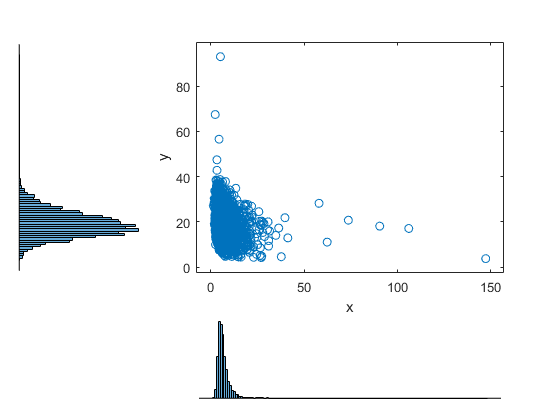

x = competition;
y = biomass;

figure;
scatterhist(x,y);

`利用`ksdensity`（）进行参数核密度估计，使用累积分布函数的核估计将数据转换为`copula`尺度，即[0~1]`

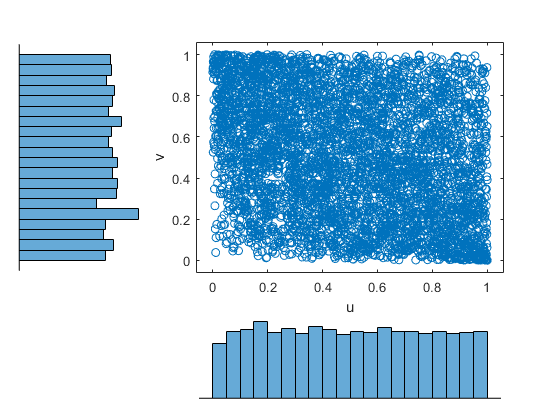

u = ksdensity(x,x,'function','cdf');
v = ksdensity(y,y,'function','cdf');
figure;
scatterhist(u,v)
xlabel('u')
ylabel('v')

`利用`copulafit`（）进行不同类型`copula`函数的拟合，求得对应参数`

rng default  % For reproducibility
[Rho,nu] = copulafit('t',[u v],'Method','ApproximateML')

Rho =     1.0000   -0.3162
   -0.3162    1.0000


nu = 19.0807

rng default  % For reproducibility
rhohat = copulafit('Gaussian',[u v])

rhohat =     1.0000   -0.3197
   -0.3197    1.0000


rng default  % For reproducibility
paramat_cla = copulafit('Clayton',[u v])

paramat_cla = 1.4509e-06

rng default  % For reproducibility
paramat_fra = copulafit('Frank',[u v])

paramat_fra = -1.8958

rng default  % For reproducibility
paramat_gum = copulafit('Gumbel',[u v])

paramat_gum = 1.0000

调用自己编写的函数计算各类copula的aic值

aic_t = aic_count('t',2,u,v,Rho,nu)

aic_t = -534.3518

aic_Gau = aic_count('Gaussian',1,u,v,rhohat)

aic_Gau = -526.1186

aic_Cla = aic_count('Clayton',1,u,v,paramat_cla)

aic_Cla = 2.0034

aic_Fra = aic_count('Frank',1,u,v,paramat_fra)

aic_Fra = -440.7642

aic_Gum = aic_count('Gumbel',1,u,v,paramat_gum)

aic_Gum = 2.0054

uu = linspace(0,1,100);
[uu1,uu2] = meshgrid(uu,uu);

yy = copulacdf('t',[uu1(:),uu2(:)],Rho,nu);
zz = copulapdf('t',[uu1(:),uu2(:)],Rho,nu);

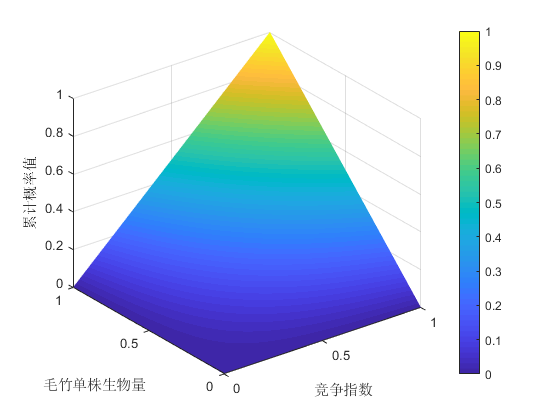

surf(uu1,uu2,reshape(yy,100,100),'FaceColor','interp','EdgeColor','none')
ylabel('毛竹单株生物量')
zlabel('累计概率值')
xlabel('竞争指数')
colorbar

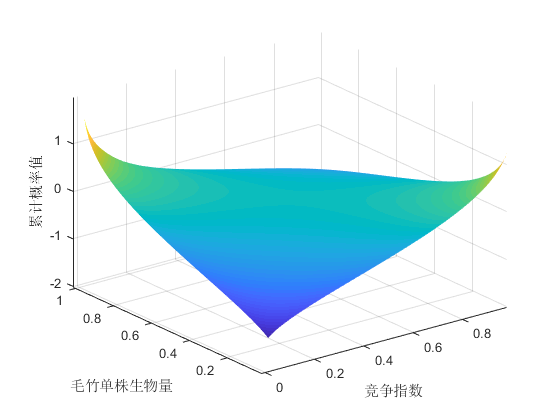

figure;
surf(uu1,uu2,log(reshape(zz,100,100)),'FaceColor','interp','EdgeColor','none')
ylabel('毛竹单株生物量')
zlabel('概率密度值')
xlabel('竞争指数')

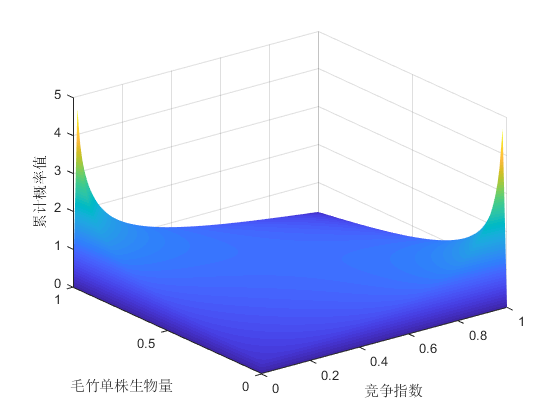

figure;
surf(uu1,uu2,reshape(zz,100,100),'FaceColor','interp','EdgeColor','none')
ylabel('毛竹单株生物量')
zlabel('累计概率值')
xlabel('竞争指数')

 r_Kendall = copulastat('t',Rho,nu)

r_Kendall =     1.0000   -0.2048
   -0.2048    1.0000



% r_ = copulastat('t',Rho,nu,'Type','Spearman')
